# Fequency Domain Analysis

### Fourier Series

`A Fourier series is an expansion of a ``periodic`` function in terms of an infinite sum of ``sines`` and ``cosines``.`

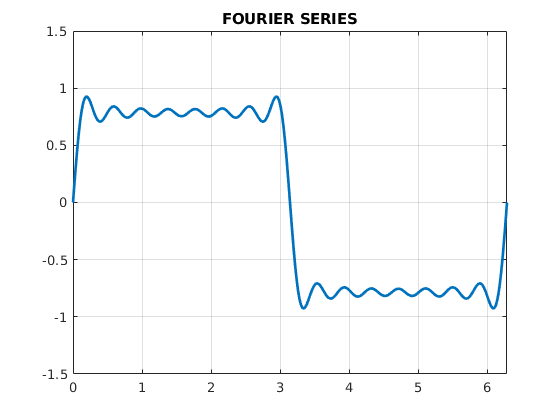

N = 16;

t = linspace(0, 2 * pi, 300);
y = zeros(size(t));
for i = 1 : 2 : N
    y = y + (1 / i) * sin(i * t);
end

plot(t, y, 'LineWidth', 2);
grid on;
xlim([0, 2 * pi]);
ylim([-1.5, 1.5]);
title("FOURIER SERIES");

### Fourier Transform

`Decomposes a non-periodic signal into its frequency components. `

`The Discrete Fourier Transfrom (DFT)`` of a signal x[n] is given by-`

`Fast Fourier Transform (FFT)`` is an algorithm that performs the forurier transform of a function in a efficient way. You can use the MATLAB ``fft()`` function to perform discrete fourier transform.`

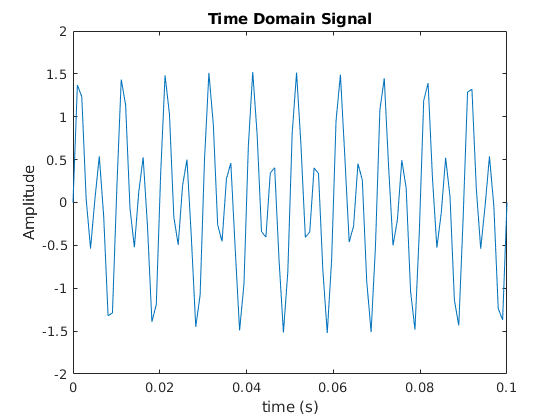

f1 = 100;
f2 = 200;
Fs = 1000;
T = 0.1;
L = Fs * T;
t = linspace(0, T, L);
x = 0.7*sin(2*pi*f1*t) + sin(2*pi*f2*t);
plot(t, x);
title("Time Domain Signal")
xlabel("time (s)");
ylabel("Amplitude");

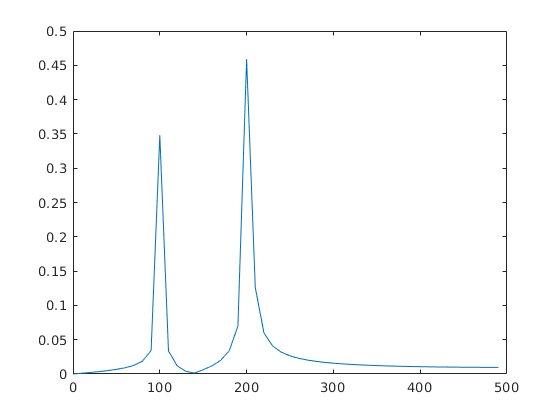

X = fft(x);
P = abs(X / L);
P1 = P(1 : L / 2);
F = (0 : L / 2 - 1) * (Fs / L);
plot(F, P1);

### WELCH METHOD

`You can get the power spectral density (PSD) of a signal using the ``pwelch()`` function.`

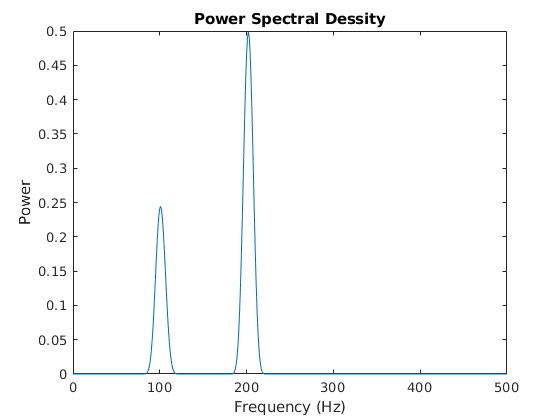

[X, F] = pwelch(x, L, L / 2, 1000, Fs, 'power');
plot(F, X);
title("Power Spectral Dessity")
xlabel("Frequency (Hz)");
ylabel("Power")